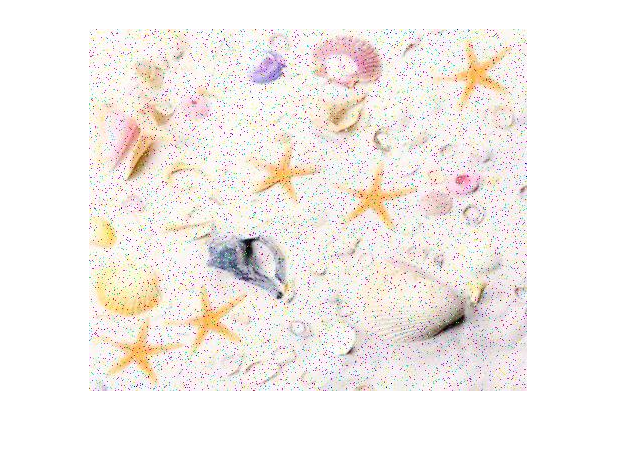

% Computer Vision Coursework Pipeline
% Write the file name to load below, with the extesion, It will
% be expected that it is located within the current directory
FileName = "StarFish.jpg";
%FileName = "starfish_5.jpg";
%Image Variable that will not be editied (Original)
OriginalImage = LoadImage(FileName);

The first task, after loading the image is to analyse the image histogram and decide what to do with the image

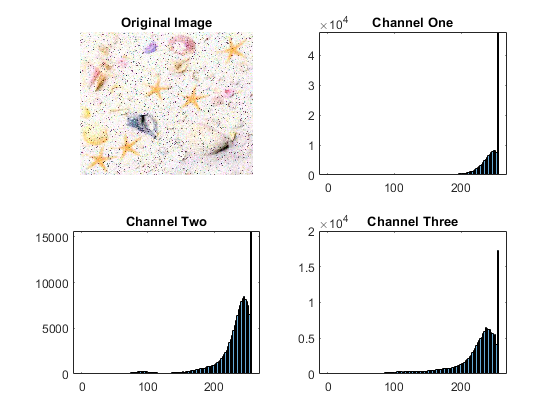

[r,g,b] = ThreeChannelHistorgram(OriginalImage);

red Channel salt and pepper noise


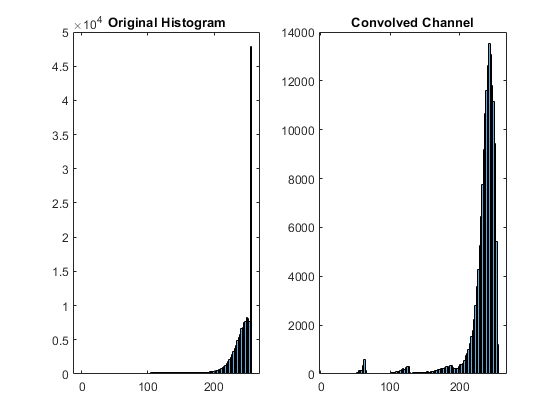


if r(length(r)) > mean(r) || r(1) > mean(r)
    disp("red Channel salt and pepper noise");
    % Add forloop until above condition is fixed?
    red = SingleChannelConvolve(OriginalImage(:,:,1), 1/(4 * 4) * ones(4));
end

Green Channel Salt and Pepper Noise


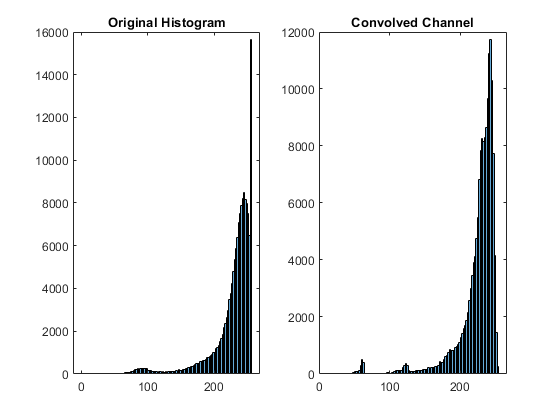

if g(length(g)) > mean(g) || g(1) > mean(g)
    disp("Green Channel Salt and Pepper Noise");
    green = SingleChannelConvolve(OriginalImage(:,:,2), 1/(4 * 4) * ones(4));
end

Blue Channel Salt and Pepper Noise


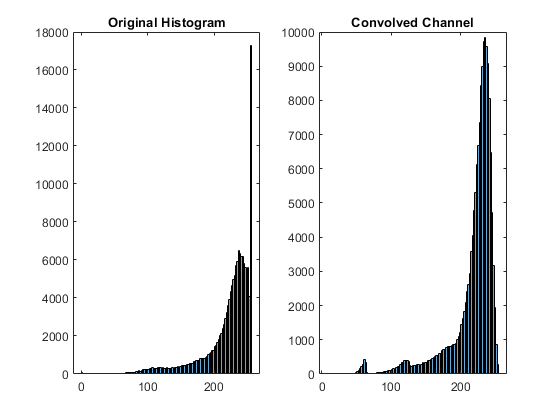

if b(length(b)) > mean(b) || b(1) > mean(b)
    disp("Blue Channel Salt and Pepper Noise")
    blue = SingleChannelConvolve(OriginalImage(:,:,3), 1/(4 * 4) * ones(4));
end

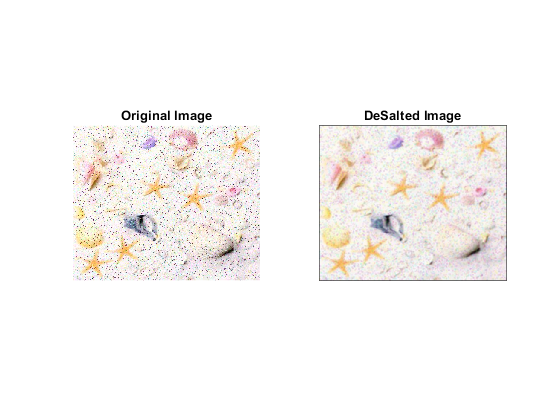

DeSaltedImage = cat(3,red, green, blue);
figure
subplot(1,2,1);
imshow(OriginalImage);
title("Original Image");
subplot(1,2,2);
imshow(DeSaltedImage);
title("DeSalted Image");

## Now moving from image prepocessing to image analysis